% Exercise 1 data generation (genGauss function)
% Generate samples for each class

% Question 1

muA = [0; 4; 7];
SigmaA = [4 -6 8;
          -6 12 -9;
          8 -9 20];

muB = [3; 9; -1];
SigmaB = [3.0184  0.4331 -1.4481;
    0.4331  0.9436 -0.6456;
    -1.4481 -0.6456  1.2880];

muC = [2; 1; 3];
SigmaC = [6.8928 -1.3750  3.1945;
    -1.3750  3.3572  0.6945;
    3.1945  0.6945  3.7500];

muD = [-1; 8; 12];
SigmaD = [6.8928 -1.3750  3.1945;
    -1.3750  3.3572  0.6945;
    3.1945  0.6945  3.7500];

muE = [-3; 10; 9];
SigmaE = [6.8928 -1.3750  3.1945;
    -1.3750  3.3572  0.6945;
    3.1945  0.6945  3.7500];

X_a = genGauss(750000, muA, SigmaA);  % K×3
X_b = genGauss(190000, muB, SigmaB);
X_c = genGauss(45000, muC, SigmaC);
X_d = genGauss(12000, muD, SigmaD);
X_e = genGauss(3000, muE, SigmaE);

% Stack into input matrix: each COLUMN is one sample
X = [X_a; X_b; X_c; X_d; X_e]';   % 3 × 3000


labels = [ones(750000,1)*1; ones(190000,1)*2; ones(45000,1)*3; ones(12000,1)*4; ones(3000,1)*5];

% Question 2

indices=randperm(1000000);

train_indices = indices(1:100000);
test_indices = indices(100001:end);

length(train_indices)

ans = 100000

length(test_indices)

ans = 900000


train_X = X(:, train_indices)

train_X =    -0.6685    0.7065   -0.2671    4.8749    2.0055    3.1541    2.4467    5.6537   -1.1382   -0.2769    0.6240    2.5257   -0.5168    1.7523   -0.3054   -0.0472   -3.9703    3.5864    2.6398    3.7616   -0.5077   -0.3938    0.3169    1.3238    0.3557    0.5400   -4.0512   -0.9417    2.4763   -1.9046   -0.7739    1.4780    1.1946   -1.3959   -0.4487    5.3331   -1.7861    1.1185   -1.3195    0.3992    1.1744    0.1116   -2.2178    6.5333    0.6780    0.0614    1.1379   -1.1196   -1.2804    2.0973
    4.3974    3.0895    1.1569   10.3781    1.0015    0.1293    8.6940   10.3007    5.7181    3.5330    8.7909    7.5405    7.2880    0.7377    5.0862    0.2437    7.2482   10.5232    0.5151    9.2171    3.2700    3.5821    5.4012    3.2277    4.0670    1.8056   10.4160    7.1663   -0.7874    9.2594    5.8840    3.4748    0.3129    6.1047    3.3222    8.8237    6.3475   -0.5258    4.1211    8.7509    2.5131    3.4745    6.5778   -3.5368    3.5433    2.8016    2.3336    3.8301    5.898

test_X = X(:, test_indices)

test_X =    -2.6617    3.0836   -0.9500    1.4380    2.2797   -3.7155    1.4802   -1.5492    1.7023    2.0659    0.1430   -0.6576    1.2378    2.2745    0.2161    4.1735    0.4226    2.3968    3.5244    1.2367    3.1264   -0.8620    0.0544    0.6838    3.9965   -0.9405    1.9158   -3.1218   -0.0236    2.3968    1.3271    4.5972   -2.0786   -1.8403    2.3704    1.3216    2.2735    2.1350   -3.7661   -4.2621    2.2189    2.6394    0.1351    4.6127    3.9811   -0.1387    2.0942   -2.1321    3.8942   -0.2411
    6.6734    7.4456    5.9920    9.7928    2.6994   12.4676    9.4648    7.6288    8.1770    1.6884    0.9881    3.5945    2.2685    2.1163    4.1477    9.7732    5.2470    0.3601    9.3060    2.2488    2.4163    6.7112    2.3132    4.9914    1.4262    1.7716    8.9922    8.2449   12.1488    0.9261    4.0411   10.0028    9.8754    4.3173    1.4898    3.4563    7.8093    4.0367    8.7378    9.1028    8.6726    0.4664    1.3086    9.1904    0.4726    4.3640    2.2990    9.8632   -1.3662

train_labels = labels(train_indices);
test_labels = labels(test_indices);

num_A_samples = sum(train_labels == 1)

num_A_samples = 74894

num_B_samples = sum(train_labels == 2)

num_B_samples = 19098

num_C_samples = sum(train_labels == 3)

num_C_samples = 4426

num_D_samples = sum(train_labels == 4)

num_D_samples = 1280

num_E_samples = sum(train_labels == 5)

num_E_samples = 302

% Question 3 - Neural Network

% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 10-Jun-2026 00:14:03
%
% This script assumes these variables are defined:
%
%   X - input data.
%   T - target data.

inputs = train_X;
T = ind2vec(labels');
size(T)

ans =            5     1000000


train_T = T(:, train_indices);
targets = train_T;

size(inputs)

ans =            3      100000


size(targets)

ans =            5      100000


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.
Cannot perform computations on a GPU.
Parallel Computing Toolbox license is not available.


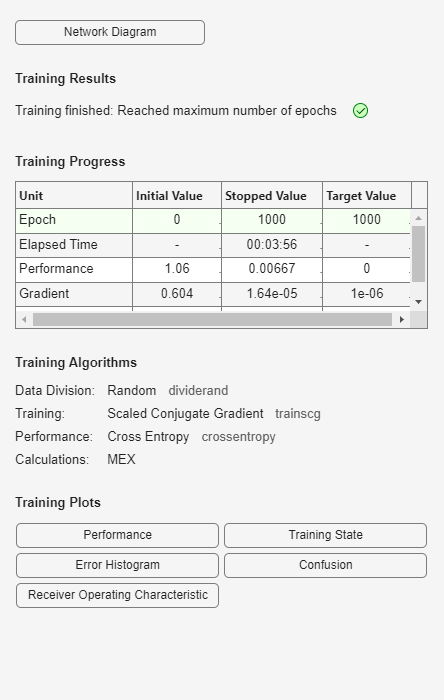


% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 100/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 0/100;

% Train the Network
[net,tr] = train(net,inputs,targets, 'UseParallel', 'yes','UseGPU','yes');

y = net(inputs);
e = gsubtract(targets,y);
performance = perform(net,targets,y)

performance = 0.0067

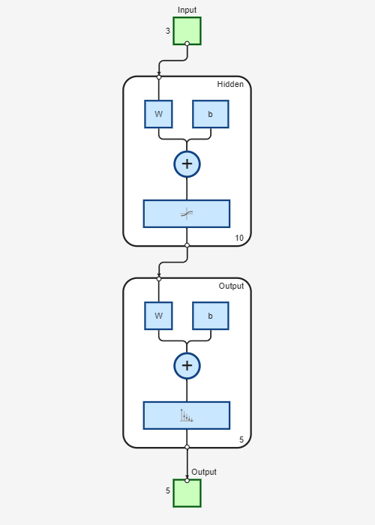

tind = vec2ind(targets);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);

% View the Network
view(net)

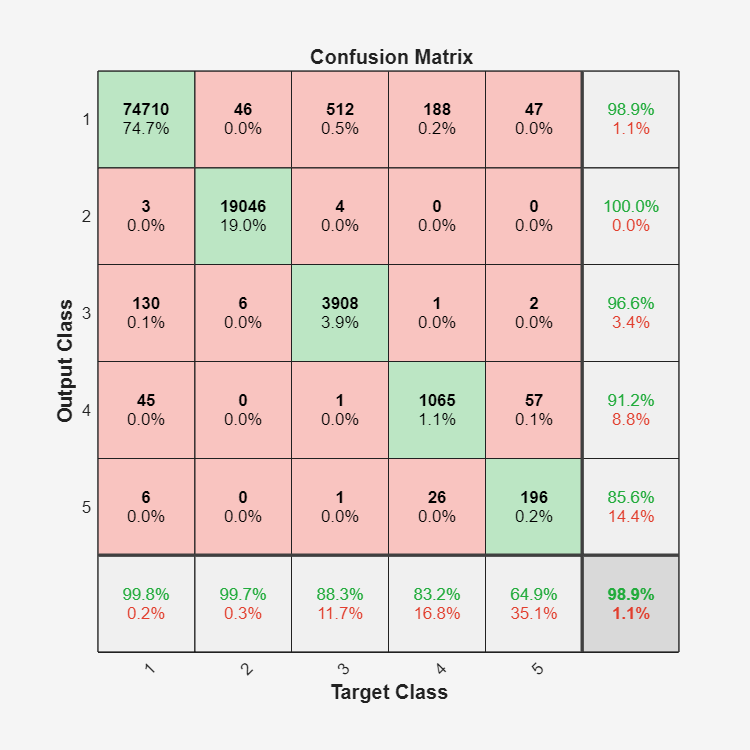


% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
figure, plotconfusion(targets,y)

%figure, plotroc(t,y)

% Question 3 - Bayes Classifier
% Train the bayes classifier on the guassian data
model = fitcdiscr(train_X', train_labels);

Question 4

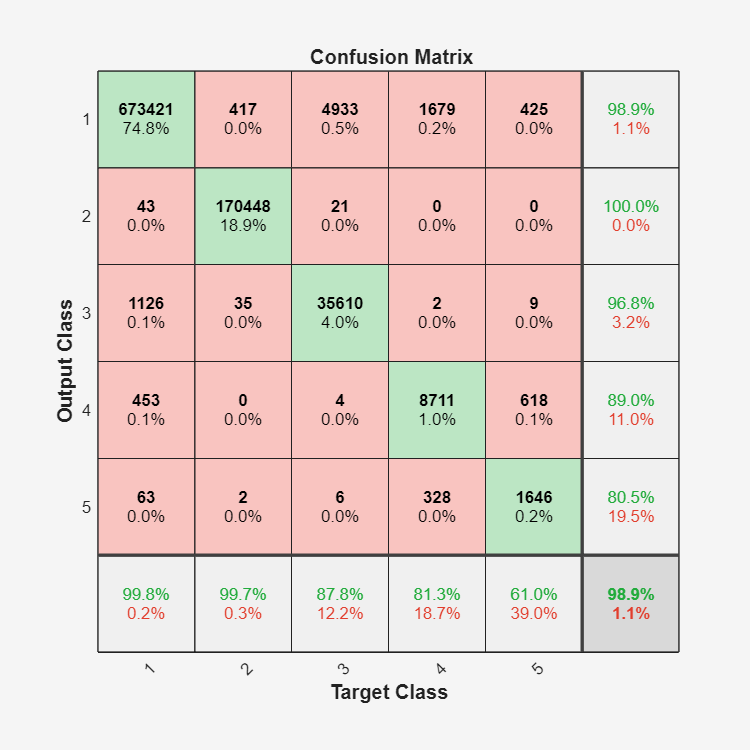

% Test the neural network on test data
test_y = net(test_X);
test_T = T(:, test_indices);
plotconfusion(test_T, test_y)

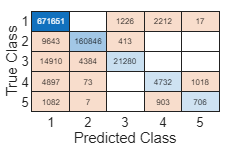


% test the bayes classifier
predicted_labels = predict(model, test_X');
figure;
confusionchart(test_labels, predicted_labels)

Accuracy drops as we move from class A to class E because the number of training samples decreases, from 99.8% for Class A down to 58.8% for Class E in the neural network, and even worse in the Bayes classifier. The number of false negatives increases accordingly. Fewer samples don't allow the models to learn the underlying patterns in the data, and therefore when it is not confident about a specific sample, it defaults to the class with higher frequency (Class A with 74,918 training samples, representing 75% of all training data). Class E performs well on the train set (80.3%) but poorly on the test set (58.8%) because with only 292 training samples, the model memorizes them instead of learning generalizable patterns, resulting in overfitting.

Question 5) 

Neural networks significantly outperform Bayes classifiers on unbalanced data. The neural network achieved 99.8% accuracy on Class A down to 58.8% on Class E, while the Bayes classifier collapsed almost entirely toward Class A, correctly identifying Class E only ~18% of the time. This difference arises because Bayes classifiers explicitly compute prior probabilities from class frequencies, with 75% of samples belonging to Class A, P(Class A) = 0.75 dominates every classification decision, creating a severe bias toward majority classes. Neural networks, being non-parametric, do not use priors explicitly, instead they learn decision boundaries through backpropagation, making them inherently less sensitive to class frequency imbalance. However, neural networks are not immune, Class E still shows a significant gap between training (80.3%) and test (58.8%) accuracy, indicating overfitting due to insufficient minority class samples. This suggests that while non-parametric approaches are more robust to unbalanced data, severe imbalance ultimately limits both approaches.

Question 6)

The likelihood of drawing samples from each class into the training set follows a **Binomial distribution**, as each sample is either drawn or not (a Bernoulli trial), and we are counting successes over 100,000 draws. The expected number of training samples for each class is E[X] = n × p, where n = 100,000 and p = class size / 1,000,000.

- Class A: p = 0.75, expected = 75,000, actual = 74,918

- Class B: p = 0.19, expected = 19,000, actual = 18,993

- Class C: p = 0.045, expected = 4,500, actual = 4,591

- Class D: p = 0.012, expected = 1,200, actual = 1,206

- Class E: p = 0.003, expected = 300, actual = 292

For Class E, the standard deviation is σ = √(n × p × (1-p)) = √(100,000 × 0.003 × 0.997) = 17.29. Using a normal approximation of the Binomial, 99% of outcomes fall within ±2.576σ of the mean, giving a range of 300 ± 44.55, meaning between **255 and 345** Class E samples will be drawn into training with 99% probability. As Class E size increases to 30,000 (p = 0.03), σ increases to 53.94 and the range widens to 2,861–3,139. While the absolute range widens with larger class sizes, the range as a proportion of the expected value narrows, meaning larger classes are relatively more predictable in their training representation.

% Question 7

idx_A = find(train_labels == 1);
idx_B = find(train_labels == 2);
idx_C = find(train_labels == 3);
idx_D = find(train_labels == 4);
idx_E = find(train_labels == 5);

min_samples = min([length(idx_A), length(idx_B), length(idx_C), length(idx_D), length(idx_E)]);

balanced_A = idx_A(randperm(length(idx_A), min_samples));
balanced_B = idx_B(randperm(length(idx_B), min_samples));
balanced_C = idx_C(randperm(length(idx_C), min_samples));
balanced_D = idx_D(randperm(length(idx_D), min_samples));
balanced_E = idx_E(randperm(length(idx_E), min_samples));

balanced_indices = [balanced_A(:); balanced_B(:); balanced_C(:); balanced_D(:); balanced_E(:)];

ans =         1510           1


balanced_X = train_X(:, balanced_indices);
balanced_labels = train_labels(balanced_indices);

size(balanced_labels)

% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 10-Jun-2026 00:14:03
%
% This script assumes these variables are defined:
%
%   X - input data.
%   T - target data.

inputs = balanced_X;

ans =            3        1510


balanced_T = ind2vec(balanced_labels');

ans =            5        1510


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.
Cannot perform computations on a GPU.
Parallel Computing Toolbox license is not available.


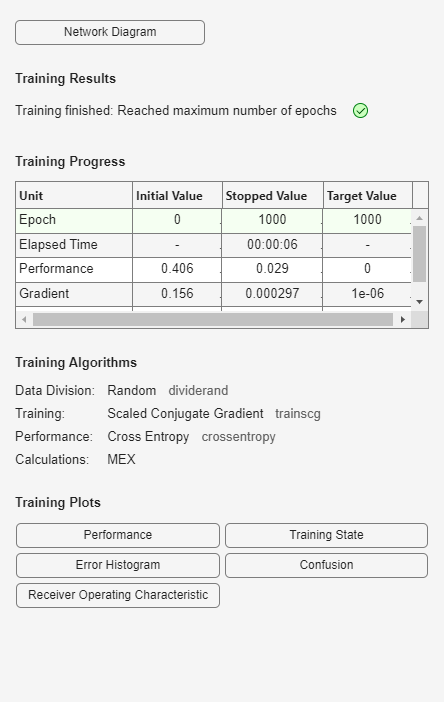

targets = balanced_T;

size(inputs)
size(targets)

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 100/100;
net.divideParam.valRatio = 0/100;

net.divideParam.testRatio = 0/100;

% Train the Network

performance = 0.0290

[net,tr] = train(net,inputs,targets, 'UseParallel', 'yes','UseGPU','yes');
y = net(inputs);
e = gsubtract(targets,y);
performance = perform(net,targets,y)
tind = vec2ind(targets);
yind = vec2ind(y);

percentErrors = sum(tind ~= yind)/numel(tind);

% View the Network
view(net)

% Plots
% Uncomment these lines to enable various plots.
%figure, plotperform(tr)
%figure, plottrainstate(tr)
%figure, ploterrhist(e)
% figure, plotconfusion(targets,y)
%figure, plotroc(t,y)


%plot the confusion matrix for test data
test_y_balanced = net(test_X);
plotconfusion(test_T, test_y_balanced)

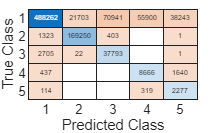

% Train the bayes classifier on the guassian data
model = fitcdiscr(balanced_X', balanced_labels);


% test the bayes classifier
predicted_labels = predict(model, test_X');
figure;
confusionchart(test_labels, predicted_labels)

Balancing the training data significantly improved classification performance for minority classes in both classifiers. The Bayes classifier benefited the most, Class E accuracy jumped from ~18% to ~84% and Class D from ~63% to ~83%, because balancing removes the prior probability bias toward Class A that was dominating its decisions. The neural network also improved on minority classes (Class E: 58.8% → 86.9%, Class D: 81.8% → 86.0%), though the gains were smaller since it was already more robust to imbalance. Both balanced classifiers sacrificed some majority class accuracy (Class A dropped from ~99.8% to ~91% for NN and ~72% for Bayes), but this is an acceptable tradeoff, the goal is to classify all classes well, not just the dominant one. Overall, the balanced Bayes classifier performed best on minority classes while the balanced neural network achieved the best overall accuracy across all five classes.

Question 8)

The three core approaches to addressing unbalanced data are undersampling, oversampling, and a hybrid of both.

**Undersampling** reduces the majority classes down to the size of the smallest class. The main advantage is simplicity, it only uses real data samples with no synthetic generation. However, the significant drawback is that it discards large amounts of legitimate data; in our case, Class A was reduced from 74,918 samples to just 290, throwing away over 99% of available data and potentially losing important patterns.

**Oversampling** increases minority classes up to the size of the majority class, either by duplicating existing samples or generating synthetic ones (e.g. SMOTE). The advantage is that all real data is retained and majority class accuracy is preserved. However, duplicating or synthesizing minority samples increases the risk of overfitting, as the classifier may memorize duplicated samples rather than learning generalizable patterns.

**Hybrid** approaches combine both strategies, partially undersampling the majority class and partially oversampling the minority class. This avoids the extremes of either approach alone: less data is discarded compared to pure undersampling, and fewer synthetic samples are needed compared to pure oversampling, reducing the risk of overfitting while still achieving a more balanced dataset. The tradeoff is increased implementation complexity and the need to tune how much to undersample and oversample for each class.

Question 9)

Formally identifying and quantifying imbalance is not always straightforward. For **labelled data**, quantifying imbalance is simple, class frequencies can be directly counted and compared, as we did by computing the proportion of each class in our dataset. For **unlabelled data** however, the degree of imbalance is much harder to quantify since class membership is unknown. In this case, **clustering techniques** such as k-means can be applied to group data into clusters, and the relative sizes of those clusters can serve as a proxy for class imbalance.

The degree of imbalance can also change as more data is collected. If the underlying events are **season-dependent** or driven by external factors, such as network attacks increasing during certain periods, the class distribution may shift significantly over time. Even if the underlying probabilities remain constant, early data collection may not yet reflect the true long-term distribution, meaning a dataset that appears balanced initially may reveal imbalance as more samples are gathered. This highlights the importance of continuously monitoring and reassessing the balance of a dataset throughout the data collection process.